# Simple scalar interpolation examples

clear ; close ; path=pwd();
[s,e]=regexp(path,'.+(?=[\\/]{1,2}examples)');
path=path(s:e); addpath(genpath(path)); clear s e path

## 1) Definition of the domain

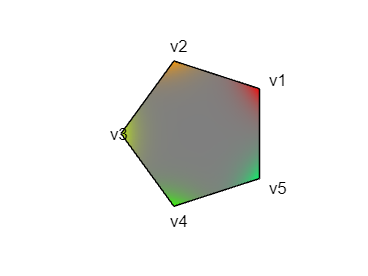

domain2D = Domain(5); % regular pentagon
figure()
domain2D.plot();

## 2) Definition of the scalar properties at each vertex

f1s = VertexFunction(@(a) a.^2, @(a) 2*a, "a^2");
f2s = VertexFunction(@(a) a.^3, @(a) 3*a.^2, "a^3");
f3s = VertexFunction(@(a) 0.1*a, @(a) 0.1*ones(size(a)), "0.1*a"); % linear
f4s = VertexFunction(@(a) ones(size(a)), @(a) zeros(size(a)), "1"); % constant
f5s = VertexFunction(@(a) 1./a, @(a) -1./(a.^2), "1/a"); % nonregular in 0

## 3) Definition of the interpolation

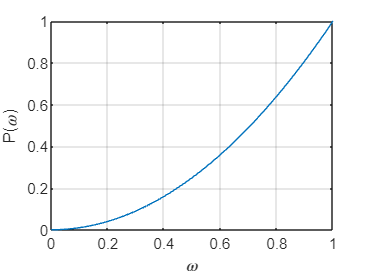

defInterpScalar.Domain = domain2D;
defInterpScalar.Children = [f1s,f2s,f3s,f4s,f5s];
defInterpScalar.Label = "interpScalar";

P = Penalization("simp",2);
defInterpScalar.Penalization = P;
P.plot();


interpScalar=Interpolation(defInterpScalar);

## 4) Definition of the variables

### a) Coordinates in the polygon

n = 1e3; % number of evaluation points
x = interpScalar.initializeVariable(n,"rand",0.9)

x = struct with fields:
    interpScalar: [1000×2 double]


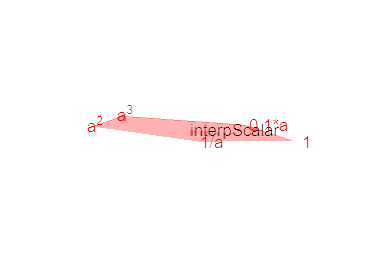

x = interpScalar.projection(x);
figure()
interpScalar.plot(x);

### b) Scalar field

Each point $x$ is associated to a scalar field value $a$.

a = rand(1,1,n);

## 5) Evaluation of the interpolation

### a) Interpolated value

tic
val = interpScalar.eval(x,a); % value
tv1 = toc;
disp(strcat("Compute interpolated values in ",num2str(tv1*1000)," ms"))

Compute interpolated values in 17.0885 ms


### b) Derivative w. r. t. the scalar field

tic
dvalda =  interpScalar.evalda(x,a); % derivative w.r.t a
tda1 = toc;
disp(strcat("Compute interpolated a-derivative in ",num2str(tda1*1000)," ms"))

Compute interpolated a-derivative in 13.592 ms


#### Check the Taylor expansion

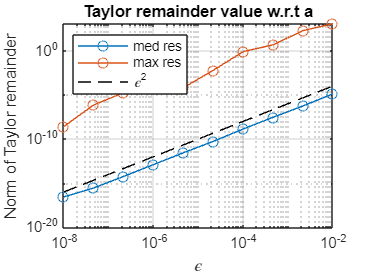

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);

for i=1:10
    pert = epsilon(i)*rand(size(a));
    valPerturbeda = interpScalar.eval(x,a+pert);
    res(i,1,:) = vecnorm(valPerturbeda - (val + mult(dvalda,pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t a")
grid on

### c) Derivative w. r. t. the position in the interpolation domain

tic
dvaldx =  interpScalar.evaldx(x,a); % derivative w.r.t x
tdx1 = toc;
disp(strcat("Compute interpolated x-derivative in ",num2str(tdx1*1000)," ms"))

Compute interpolated x-derivative in 21.7354 ms


#### Check the Taylor expansion

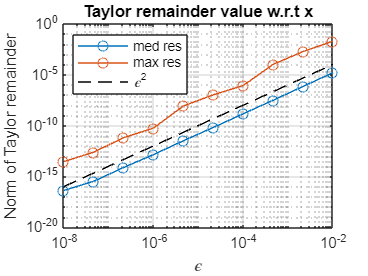

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);
l = defInterpScalar.Label;

for i=1:10
    pert = epsilon(i)*rand(size(x.(l)));
    xPert.(l) = x.(l) + pert;
    valPerturbedx = interpScalar.eval(xPert,a);
    pert = reshape(pert.',2,1,[]);
    res(i,1,:) = vecnorm(valPerturbedx - (val + mult(dvaldx.(l),pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t x")
grid on

## 6) Speed tip

To compute several times the interpolation for different $a$ without changing the position $x$ in the domain, one should first compute the shape functions once for all.

a2 = rand(100,1,n);
% slow
tic
for i=1:100
    interpScalar.eval(x,a2(i,1,:)); % value
    interpScalar.evalda(x,a2(i,1,:)); % derivative w.r.t a
    interpScalar.evaldx(x,a2(i,1,:)); % derivative w.r.t x
end
tslow = toc;
disp(strcat("Computation time : ",num2str(tslow)," s"))

Computation time : 0.42377 s



% fast
tic
 % pre-computation of the shape functions
[w,dwdx] = interpScalar.evalBasisFunction(x);
for i=1:100
    interpScalar.eval(x,a2(i,1,:),w); % value
    interpScalar.evalda(x,a2(i,1,:),w); % derivative w.r.t a
    interpScalar.evaldx(x,a2(i,1,:),w,dwdx); % derivative w.r.t x
end
tfast = toc;
disp(strcat("Computation time : ",num2str(tfast)," s"))

Computation time : 0.12874 s
